## load

clear all
filenameImagesTrain = 'train-images-idx3-ubyte';
filenameLabelsTrain = 'train-labels-idx1-ubyte';
filenameImagesTest = 't10k-images-idx3-ubyte';
filenameLabelsTest = 't10k-labels-idx1-ubyte';

XTrain_all = processImagesMNIST(filenameImagesTrain);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain_all = processLabelsMNIST(filenameLabelsTrain);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest_all= processImagesMNIST(filenameImagesTest);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest_all = processLabelsMNIST(filenameLabelsTest);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


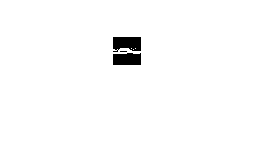

% Select label 5 and 7
XTrain = XTrain_all(YTrain_all==5|YTrain_all==7,:);
YTrain = YTrain_all(YTrain_all==5|YTrain_all==7,:);
XTest = XTest_all(YTest_all==5|YTest_all==7,:);
YTest = YTest_all(YTest_all==5|YTest_all==7,:);
YTest(YTest==5)=1;
YTrain(YTrain==5)=1;
YTest(YTest==7)=0;
YTrain(YTrain==7)=0;
test = XTest(1,:)';
test=reshape(test.*255,[28,28]);
imshow(test')

disp(YTest(1,:))

     1




clearvars -except XTrain YTrain XTest YTest

## First: Logistic Regression

Logistic regresssion in matlab doesn't have $C$, but using /lamda infront of the regularizaiton term.

%% LR C = [1e-9,1e-8,1e-7,1e-6, 1e-5, 1e-4, 1e-3, 1e-2, 1e-1, eps, 1, 1e1, 1e2, 1e3
mdl = fitclinear(XTrain, YTrain,"Learner","logistic","Regularization","lasso", "Lambda",[1e-9,1e-8,1e-7,1e-6, 1e-5, 1e-4, 1e-3, 1e-2, 1e-1, eps, 1, 1e1, 1e2, 1e3],"Solver","sgd");
Label = predict(mdl,XTest);
accuracy = sum(Label == YTest)/length(YTest)

accuracy =     0.9455    0.9345    0.9325    0.9495    0.9450    0.9445    0.9445    0.9430    0.9320    0.8825    0.7585    0.5015    0.5000    0.5000


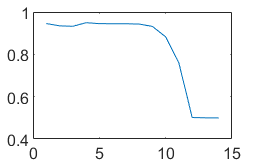

plot(accuracy)

## Second: SVM: [cjlin1/libsvm (github.com)](https://github.com/cjlin1/libsvm)


%% SVM
% C-SVM, linear
C = [1e-9,1e-8,1e-7,1e-6, 1e-5, 1e-4, 1e-3, 1e-2, 1e-1, eps, 1, 1e1, 1e2, 1e3];
accuracies = zeros(size(C));
traing_times = zeros(size(C));
models = {};
parfor i = 1:length(C)
    disp(C(i))
    tic
    model = svmtrain(YTrain,XTrain,['-s 0 -t 0 -c ', convertStringsToChars(string(C(i)))]);
    traing_times(i) = toc;
    [predicted_label, accuracy, dec_values_L] = svmpredict(YTest, XTest,model);
    accuracies(i) = accuracy(1);
    models{i} = model;  
end

   1.0000e-09

   1.0000e-08

   1.0000e-07

   1.0000e-06

   1.0000e-05

   1.0000e-04

   1.0000e-03

    0.0100

    0.1000

   2.2204e-16

    10

        1000



plot(accuracies)
plot(traing_times)

server_chan("Simulation Done")